# Second example : 

# 100 neurons during 8 seconds with a firing rate of 5 Hz, time steps of 20 ms, and a signal-to-noise ratio of 7

    clear;

## Step 1:  Set simulation parameters

    nbNeurons = 100;     
    firingRate = 5;
    totalTime = 8;
    moreOptions.timeStep = 0.02;
    moreOptions.SNR = 7;

## Step 2:  Simulate activity

    tic;
    data = PoissonNeuronActivity( nbNeurons, firingRate, totalTime, moreOptions);
    toc;

Elapsed time is 0.192839 seconds.


## Step 3:  Visualize the activity

First neuron

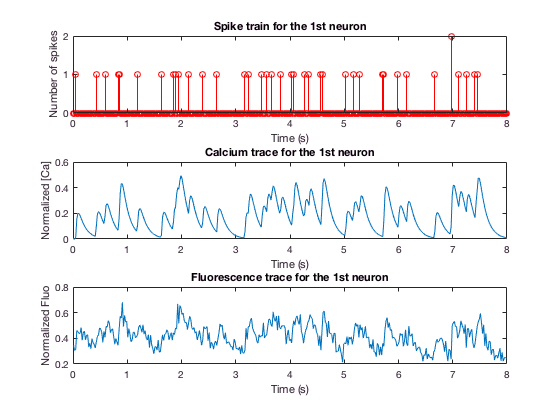

   time = data.time;
   spikeTrain = data.spikes(1,:);
   calciumTrace = data.calcium(1,:);
   fluoTrace = data.fluo(1,:);
   figure()
       subplot(3,1,1)
           stem(time,spikeTrain,'color','r');
           xlabel('Time (s)');
           ylabel('Number of spikes')
           title('Spike train for the 1st neuron');
           subplot(3,1,2)
                plot(time,calciumTrace);
                xlabel('Time (s)');
                ylabel('Normalized [Ca]')
                title('Calcium trace for the 1st neuron');
        subplot(3,1,3)
            plot(time,fluoTrace);
                xlabel('Time (s)');
                ylabel('Normalized Fluo')
                title('Fluorescence trace for the 1st neuron');

All neurons

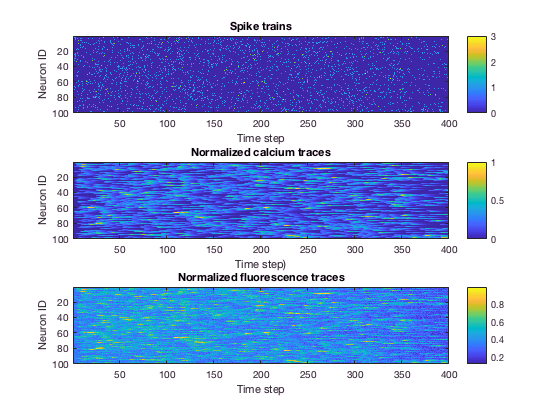

   spikeTrains = data.spikes;
   calciumTraces = data.calcium;
   fluoTraces = data.fluo;
   figure()
       subplot(3,1,1)
           imagesc(spikeTrains);colorbar;
           xlabel('Time step');
           ylabel('Neuron ID')
           title('Spike trains');
       subplot(3,1,2)
           imagesc(calciumTraces);colorbar;
           xlabel('Time step)');
           ylabel('Neuron ID')
           title('Normalized calcium traces');
        subplot(3,1,3)
           imagesc(fluoTraces);colorbar;
           xlabel('Time step');
           ylabel('Neuron ID')
           title('Normalized fluorescence traces');